Algorithm

% Maze
createMaze_1;
start = Maze.start;
goal = Maze.goal;
path = D_star(start, goal, Maze.map);

    45    45

    50    50



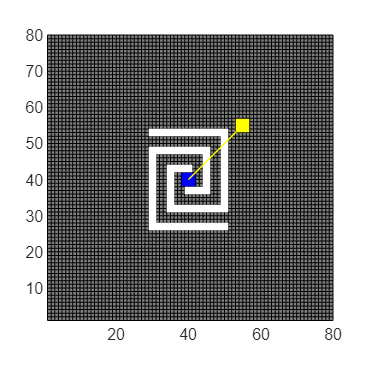


%hold on;
hold on
plot(path(:, 1), path(:, 2), 'Color', 'yellow', 'LineWidth', 1)

**Process State Function**

function [k_min, k, b, c, h, t, OPEN] = ProcessState(OPEN, t, h, b, c, k, map_size, obstacle_map)
    
    % Get state in OPEN list with minimum k(*) value. 
    x = GetMinState(OPEN, k);

    % No available state
    if isempty(x)
        k_min = -1;
        return
    end

    % Get min k from OPEN list, and removes state from OPEN list
    k_old = GetKMin(OPEN, k);
    [OPEN, t] = Delete(x, OPEN, t);

    % Lower state 
    if k_old < h(x(1), x(2))
        neighbors = GetNeighbors(x, map_size);
        for i = 1:size(neighbors, 1)
            y = neighbors(i, :);
            if h(y(1), y(2)) <= k_old && h(x(1), x(2)) > h(y(1), y(2)) + c(y, x, obstacle_map)
                b{x(1), x(2)} = y;
                h(x(1), x(2)) = h(y(1), y(2)) + c(y, x, obstacle_map);  
            end
        end

    elseif k_old == h(x(1), x(2))
        neighbors = GetNeighbors(x, map_size);
        for i = 1:size(neighbors, 1)
            y = neighbors(i, :);
            if t(y(1), y(2)) == uint32(DStarTag.NEW) ||...
                (all((b{y(1), y(2)} == x) & h(y(1), y(2)) ~= h(x(1), x(2)) + c(x, y, obstacle_map))) ||...
                (any((b{y(1), y(2)} ~= x) & h(y(1), y(2)) > h(x(1), x(2)) + c(x, y, obstacle_map)))
                    b{y(1), y(2)} = x;
                    [k, h, t, OPEN] = Insert(y, h(x(1), x(2)) + c(x, y, obstacle_map), h, t, k, OPEN);
            end
        end
    else
        neighbors = GetNeighbors(x, map_size);
        for i = 1:size(neighbors, 1)
            y = neighbors(i, :);
            if t(y(1), y(2)) == uint32(DStarTag.NEW) ||...
                (all(b{y(1), y(2)} == x) & h(y(1), y(2)) ~= h(x(1), x(2)) + c(x, y, obstacle_map))
                    b{y(1), y(2)} = x;
                    [k, h, t, OPEN] = Insert(y, h(x(1), x(2)) + c(x, y, obstacle_map), h, t, k, OPEN);
            else
                if any(b{y(1), y(2)} ~= x) & h(y(1), y(2)) > h(x(1), x(2)) + c(x, y, obstacle_map)
                    [k, h, t, OPEN] = Insert(x, h(x(1), x(2)), h, t, k, OPEN);
                elseif any(b{y(1), y(2)} ~= x) & h(x(1), x(2)) > h(y(1), y(2)) + c(y, x, obstacle_map) & t(y(1), y(2)) == uint32(DStarTag.CLOSED) & h(y(1), y(2)) > k_old
                    [k, h, t, OPEN] = Insert(y, h(y(1), y(2)), h, t, k, OPEN);
                end
            end
        end
    end

    k_min = GetKMin(OPEN, k);
end

function neighbors = GetNeighbors(state, gridSize)
    % Get valid neighbors within the grid boundaries
    x = state(1);
    y = state(2);
    neighbors = [];
    for dx = -1:1
        for dy = -1:1
            newX = x + dx;
            newY = y + dy;
            if newX >= 1 && newX <= gridSize(1) && newY >= 1 && newY <= gridSize(2)
                neighbors = [neighbors; newX, newY];
            end
        end
    end
end

function [k, h, t, OPEN] = Insert(x, h_new, h, t, k, OPEN)
    if t(x(1), x(2)) == uint32(DStarTag.NEW)
        k(x(1), x(2)) = h_new;
    
    elseif t(x(1), x(2)) == uint32(DStarTag.OPEN)
            k(x(1), x(2)) = min(k(x(1), x(2)), h_new);
    
    elseif t(x(1), x(2)) == uint32(DStarTag.CLOSED)
            k(x(1), x(2)) = min(h(x(1), x(2)), h_new);
    end

    % Update h values of the state
    h(x(1), x(2)) = h_new;
    % Set state tag to OPEN
    t(x(1), x(2)) = uint32(DStarTag.OPEN);

    % Add or reposition state in the OPEN list sorted by k values
    if isempty(OPEN)
        OPEN = [x];
    else
        OPEN = [OPEN; x];
        % Compute key values for all states in the OPEN list
        keys = zeros(size(OPEN, 1), 1);
        for i = 1:size(OPEN, 1)
            keys(i) = k(OPEN(i, 1), OPEN(i, 2));
        end
    
        % Find the index to insert the new state based on its key value
        [~, idx] = sort(keys);
        OPEN = OPEN(idx(:, 1), :);
    end

end

% Removes x from OPEN list
function [OPEN, t] = Delete(x, OPEN, t)
    OPEN = OPEN(~(OPEN(:, 1) == x(1) & OPEN(:, 2) == x(2)), :);
    t(x(1), x(2)) = uint32(DStarTag.CLOSED);
end

% Get state with minimum k value from OPEN list
function X = GetMinState(OPEN, k)
    minK = inf;
    X = [];
    for i = 1:size(OPEN, 1)
        if k(OPEN(i, 1), OPEN(i, 2)) < minK
            minK = k(OPEN(i, 1), OPEN(i, 2));
            X = OPEN(i,:);
        end
    end
end

% Get minimum k value from OPEN list
function k_min = GetKMin(OPEN, k)
    if isempty(OPEN)
        k_min = -1;
    else
        k_min = Inf;
        for i = 1:size(OPEN, 1)
            % Update k_min by comparing with the h value of each state in OPEN
            k_min = min(k_min, k(OPEN(i, 1), OPEN(i, 2)));
        end
    end
end

% Computes the arc cost going from state x to state y.
function c = ArcCost(x, y, obstacle_map)
    c = obstacle_map(y(1), y(2)) + abs(y(1) - x(1)) + abs(y(2) - x(2));
end

**D* Algorithm**

function path = D_star(start, goal, map)
    % Initialize variables
    assignin('base','TAG_NEW', 0);
    assignin('base','TAG_OPEN', 1);
    assignin('base','TAG_CLOSED', 2);
    gridSize = size(map);
    h = ones(gridSize);  % Path cost estimates
    b = cell(gridSize);   % Back pointers
    t = zeros(gridSize);  % Tags for each state
    k = zeros(gridSize);    % Key function values for each state
    obstacle_map = ones(gridSize);
    OPEN = [];            % States on the OPEN list

    % Arc cost function, map value of neighbour state + euclidian distance,
    % where map values are 0 for free space, inf for obstacles.
    c = @ArcCost; 

    % 1. Initialize
    h(goal(1), goal(2)) = 0;
    OPEN = [OPEN; goal];
    
    % Initializes the back pointers to a valid state in the map.
    for i = 1:gridSize(1)
        for j = 1:gridSize(2)
            b{i, j} = [1, 1];
        end
    end

    % 2. Repeatedily process state until the robot's state is removed from
    % the OPEN list, or a value of -1 is returned (state does not exist).
    X = start;
    k_min = 0;
    while t(start(1), start(2)) ~= uint32(DStarTag.CLOSED) && k_min ~= -1
        [k_min, k, b, c, h, t, OPEN] = ProcessState(OPEN, t, h, b, c, k, gridSize, obstacle_map);
    end

    % 3. Move the robot according to the back pointers.
    path = start;
    current = start;
    while any(current ~= goal)
        next = b{current(1), current(2)};

        % If next state is an obstacle, modify the arc cost and re-process
        % the state until the path cost of the next state is less than the
        % minimum of k of the states in the OPEN list.
        if map(next(1), next(2)) == Inf
            [k_min, OPEN, h, b, obstacle_map, t, k] = ModifyCost(current, next, obstacle_map, Inf, OPEN, h, b, t, k);
        end
            while k_min >= h(next(1), next(2))
                [k_min, k, b, c, h, t, OPEN] = ProcessState(OPEN, t, h, b, c, k, gridSize, map);
            end

            current = b{current(1), current(2)};
            path = [current; path];
    end
end

% Modifies the arc cost and add state x back to the OPEN list if it was on the
% CLOSED list.
function [k_min, OPEN, h, b, obstacle_map, t, k] = ModifyCost(x, y, obstacle_map, cval, OPEN, h, b, t, k)
    % Update arc cost function
    obstacle_map(y(1), y(2)) = cval;
    
    % If X is CLOSED, add it back to the OPEN list
    if t(x(1), x(2)) == uint32(DStarTag.CLOSED)
        [k, h, t, OPEN] = Insert(x, h(x(1), x(2)), h, t, k, OPEN);
    end
    
    k_min = GetKMin(OPEN, k);
end
